
%% Following instructions from Gard10 readme file
p = tgs_parameters_v10();
p.NG = 100;
p.seed = [153 1 39];
p.sigma = 2.5;
p.Beta = tgs_newbeta_v10(p);
p.gen = 500;



o=tgs_agard_v10(p, 1);
%c=tgs_carpet(o.trace); title('GARD'); xlabel('Generation'); ylabel('Generation');

## Find the location where the number of +- compositions that have H>=0.9 to each other is specified. Make both these numbers easy to modify at will

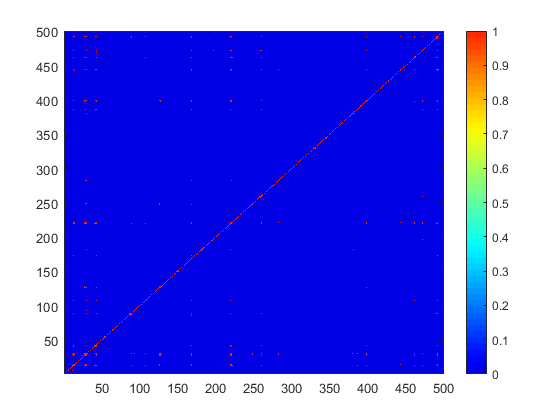

% Simulate
o = tgs_agard_v10(p, 1);
%c=tgs_carpet(o.trace); title('GARD'); xlabel('Generation'); ylabel('Generation');
% Calculate H and remove values below a threshold
H_threshold = 0.85;
H_mat = tgs_H(o.trace, o.trace);
H_mat(H_mat < H_threshold) = 0;
H_mat(H_mat >= H_threshold) = 1;


% Visulize Matrix
imagesc(H_mat,[0 1]);
set(gca,'YDir','normal');
colorbar;


% Generate a nearest neighbours matrix
